# Práctica 8 -Solución de ejercicios

### a) EDPEliptica: Ecuación de distribución de estado estable del calor (independiente del tiempo)

disp("Ejercicio 1:");

Ejercicio 1:


El método de Gauss-Seidel ha convergido después de 23 iteraciones.


w_solved =     0.6978    1.1793    1.7128    2.2907
    1.1793    1.8253    2.5339    3.2958
    1.7128    2.5339    3.4280    4.3847
    2.2907    3.2958    4.3847    5.5452


f_solved =      4     5     6     7     8
     4     5     6     7     8
     4     5     6     7     8
     4     5     6     7     8
     4     5     6     7     8


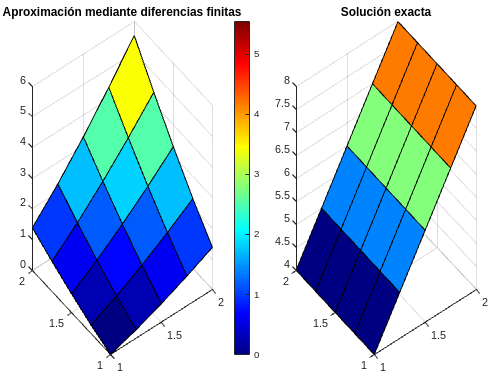

f = @(x,y) x/y + y/x;

%% Extremos del intervalo en x
a = 1; b= 2;

%% Extremos del intervalo en y
c = 1; d= 2;


n = 4; % columnas
m = 4; % filas

% mxn

%% f1 -> f2 corresponden a los extremos de y
f3 = @(x) x*log(x);
f4 = @(x) x*log(4*x^2);

%% f1 -> f2 correspoden a los extremos de x
f1 = @(y) y*log(y);
f2 = @(y) 2*y*log(2*y);

f_original = @(x, y) 4*x;

EDPElipticaGeneral(f, a, b, c, d, n, m, f1, f2, f3, f4, f_original);

### b) EDPElíptica

disp("Ejercicio 2:");

Ejercicio 2:


El método de Gauss-Seidel ha convergido después de 1187 iteraciones.


w_solved =     0.0056    0.0306    0.0756    0.1406    0.2256    0.3306    0.4556    0.6006    0.7656    0.9506    1.1556    1.3806    1.6256    1.8906    2.1756    2.4806    2.8056    3.1506    3.5156    3.9006
    0.0025    0.0225    0.0625    0.1225    0.2025    0.3025    0.4225    0.5625    0.7225    0.9025    1.1025    1.3225    1.5625    1.8225    2.1025    2.4025    2.7225    3.0625    3.4225    3.8025
    0.0006    0.0156    0.0506    0.1056    0.1806    0.2756    0.3906    0.5256    0.6806    0.8556    1.0506    1.2656    1.5006    1.7556    2.0306    2.3256    2.6406    2.9756    3.3306    3.7056
   -0.0000    0.0100    0.0400    0.0900    0.1600    0.2500    0.3600    0.4900    0.6400    0.8100    1.0000    1.2100    1.4400    1.6900    1.9600    2.2500    2.5600    2.8900    3.2400    3.6100
    0.0006    0.0056    0.0306    0.0756    0.1406    0.2256    0.3306    0.4556    0.6006    0.7656    0.9506    1.1556    1.3806    1.6256    1.8906    2.1756    2.4806    2.8056    3

f_solved =          0    0.0006    0.0025    0.0056    0.0100    0.0156    0.0225    0.0306    0.0400    0.0506    0.0625    0.0756    0.0900    0.1056    0.1225    0.1406    0.1600    0.1806    0.2025    0.2256    0.2500    0.2756    0.3025    0.3306    0.3600    0.3906    0.4225    0.4556    0.4900    0.5256    0.5625    0.6006    0.6400    0.6806    0.7225    0.7656    0.8100    0.8556    0.9025    0.9506    1.0000
    0.0100    0.0056    0.0025    0.0006         0    0.0006    0.0025    0.0056    0.0100    0.0156    0.0225    0.0306    0.0400    0.0506    0.0625    0.0756    0.0900    0.1056    0.1225    0.1406    0.1600    0.1806    0.2025    0.2256    0.2500    0.2756    0.3025    0.3306    0.3600    0.3906    0.4225    0.4556    0.4900    0.5256    0.5625    0.6006    0.6400    0.6806    0.7225    0.7656    0.8100
    0.0400    0.0306    0.0225    0.0156    0.0100    0.0056    0.0025    0.0006         0    0.0006    0.0025    0.0056    0.0100    0.0156    0.0225    0.0306    0.0

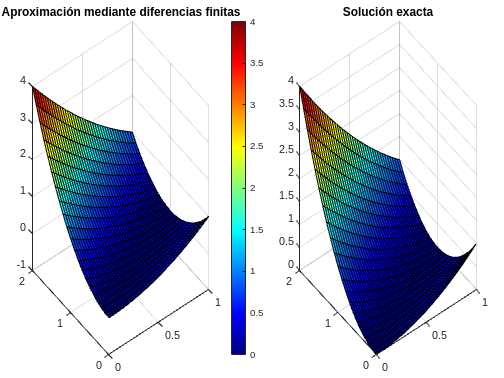


f = @(x,y) 4;

%% Extremos del intervalo en x
a = 0; b= 1;

%% Extremos del intervalo en y
c = 0; d= 2;

n = 40;
m = 20;

%% f1 -> f2 corresponden a los extremos de y
f3 = @(x) x^2;
f4 = @(x) (x-2)^2;

%% f1 -> f2 correspoden a los extremos de x
f1 = @(y) y^2;
f2 = @(y) (y-1)^2;

f_original = @(x, y) (x-y).^2;

EDPElipticaGeneral(f, a, b, c, d, n, m, f1, f2, f3, f4, f_original);

### c) EDPParabólica: Ecuación de difusión del calor a lo largo de una varilla

f = @(x) sin(2*pi*x);
l = 2;
m = 20;
n = 50;
T = 0.5;
alpha = 1;

[x, y, w] = EDPParabolica(f, l, T, alpha, n, m)

h = 0.1000

k = 0.0100

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


w =     0.5878    0.4253    0.3078    0.2227    0.1611    0.1166    0.0844    0.0611    0.0442    0.0320    0.0231    0.0167    0.0121    0.0088    0.0063    0.0046    0.0033    0.0024    0.0017    0.0013    0.0009    0.0007    0.0005    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9511    0.6882    0.4980    0.3603    0.2607    0.1887    0.1365    0.0988    0.0715    0.0517    0.0374    0.0271    0.0196    0.0142    0.0103    0.0074    0.0054    0.0039    0.0028    0.0020    0.0015    0.0011    0.0008    0.0006    0.0004    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

w(4,50)

ans = 7.6709e-08

% Buscar la columna del T dado por el ejercicio

f = @(x, t) exp(-(pi^2/4).^t).*sin((pi/2).*x);

f_solved = zeros(size(w));
x = x(2:end-1);

for i = 1:length(x)
    for a = 1:length(y)
        f_solved(i,a) = f(x(i), y(a));
    end
end

f_solved

f_solved =     0.0575    0.0570    0.0565    0.0560    0.0555    0.0550    0.0544    0.0539    0.0534    0.0529    0.0524    0.0518    0.0513    0.0508    0.0503    0.0498    0.0493    0.0487    0.0482    0.0477    0.0472    0.0467    0.0462    0.0457    0.0452    0.0447    0.0442    0.0437    0.0432    0.0427    0.0422    0.0417    0.0412    0.0407    0.0402    0.0397    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0358    0.0353    0.0349    0.0344    0.0339    0.0334    0.0330
    0.1137    0.1127    0.1116    0.1106    0.1096    0.1085    0.1075    0.1065    0.1055    0.1045    0.1034    0.1024    0.1014    0.1004    0.0993    0.0983    0.0973    0.0963    0.0953    0.0943    0.0933    0.0923    0.0912    0.0902    0.0892    0.0882    0.0872    0.0862    0.0853    0.0843    0.0833    0.0823    0.0813    0.0803    0.0794    0.0784    0.0774    0.0764    0.0755    0.0745    0.0736    0.0726    0.0717    0.0707    0.0698    0.0689    0.0679    0.0670    0.06

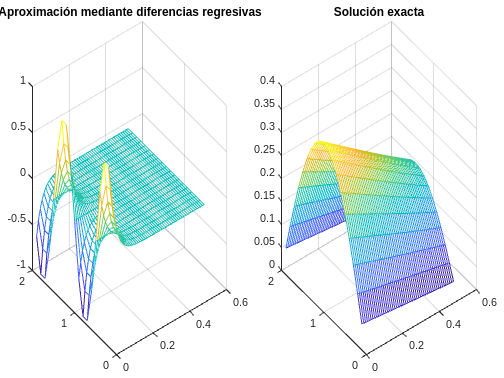

[X, Y] = meshgrid(y, x);
    
figure;
tiledlayout(1,2, 'TileSpacing', 'Compact', 'Padding', 'Compact')

nexttile
mesh(X, Y, w);
title('Aproximación mediante diferencias regresivas')

nexttile
mesh(X, Y, f_solved);
title('Solución exacta')

### d) EDPParabólica

f = @(x) sin(pi/2*x);
l = 2;
m = 3;
n = 2;
T = 0.1;
alpha = 1;

[x, y, w] = EDPParabolica(f, l, T, alpha, n, m);

h = 0.6667

k = 0.0500

% f = @(x, t) 2*exp(-((pi^2)/4).^t).*sin(2*pi.*x);
% 
% f_solved = zeros(size(w));
% x = x(2:end-1);
% 
% for i = 1:length(x)
%     for j = 1:length(y)
%         f_solved(i,j) = f(x(i),y(j));
%     end
% end
% 
% f_solved
% [X, Y] = meshgrid(y, x);    
% figure;
% tiledlayout(1,2, 'TileSpacing', 'Compact', 'Padding', 'Compact')

% nexttile
% mesh(X, Y, w);
% title('Aproximación mediante diferencias regresivas')
% 
% nexttile
% mesh(X, Y, f_solved);
% title('Solución exacta')

### e) EDPHiperbólica: Problemas físicos relacionados con vibraciones (ecuación de onda)

f = @(x) sin(2*pi*x);
g = @(x) 2*pi*sin(2*pi*x);
l = 1;
m = 10;
n = 5;
T = 0.5;
alpha = 1;
% La cuenta de las columnas empieza en 0
[x, y, w] = EDPHiperbolica(f, g, l, T, alpha, n, m)

h = 0.1000

k = 0.1000

                  K: 0.0000     K: 0.1000     K: 0.2000     K: 0.3000      K: 0.4000     K: 0.5000 
                  __________    __________    __________    __________    ___________    __________

    X : 0.1000       0.58779        0.9571       0.96084       0.59757      0.0060451      -0.58779
    X : 0.2000       0.95106        1.5486        1.5547       0.96688      0.0097812      -0.95106
    X : 0.3000       0.95106        1.5486        1.5547       0.96688      0.0097812      -0.95106
    X : 0.4000       0.58779        0.9571       0.96084       0.59757      0.0060451      -0.58779
    X : 0.5000    1.2246e-16    1.9941e-16    3.2162e-16    2.2633e-17    -3.2162e-16    1.9941e-16
    

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


y =          0    0.1000    0.2000    0.3000    0.4000    0.5000


w =     0.5878    0.9571    0.9608    0.5976    0.0060   -0.5878
    0.9511    1.5486    1.5547    0.9669    0.0098   -0.9511
    0.9511    1.5486    1.5547    0.9669    0.0098   -0.9511
    0.5878    0.9571    0.9608    0.5976    0.0060   -0.5878
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
   -0.5878   -0.9571   -0.9608   -0.5976   -0.0060    0.5878
   -0.9511   -1.5486   -1.5547   -0.9669   -0.0098    0.9511
   -0.9511   -1.5486   -1.5547   -0.9669   -0.0098    0.9511
   -0.5878   -0.9571   -0.9608   -0.5976   -0.0060    0.5878


x = x(2:end-1);
y = y(1:end-1);
f = @(x, t) sin(t)*sin(4*pi*x);

% f_solved = zeros(size(w));
% for i = 1:length(y)
%     for a = 1:length(x)
%         f_solved(a, i) = f(x(a), y(i));
%     end
% end
% 
% f_solved
% 
% [X, Y] = meshgrid(y, x);    
% figure;
% tiledlayout(1,2, 'TileSpacing', 'Compact', 'Padding', 'Compact')
% 
% nexttile
% surf(X, Y, w);
% title('Aproximación mediante diferencias regresivas')
% 
% nexttile
% surf(X, Y, f_solved);
% title('Solución exacta')

### f) Ejercicio praćtico

f = @(x,y) -1.5/1.04;

a = 0; b = 6;
f3 = @(x) x*(6-x);
f4 = @(x) 0;

c = 0; d = 5;
f1 = @(y) y*(5-y);
f2 = @(y) 0;

n = 40;
m = 20;

[x, y, w] = EDPEliptica(f, a, b, c, d, n, m, f1, f2, f3, f4);

El método de Gauss-Seidel ha convergido después de 725 iteraciones.


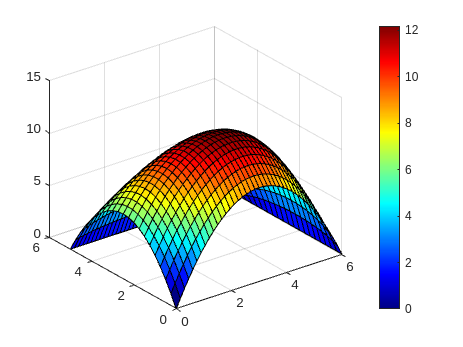

[X, Y] = meshgrid(x, y);
figure;
surf(X, Y, w');
colorbar;
colormap("jet");